# HW 4 deals with z transforms and simulink

## Problem 1


clc; clear all; 
syms z

n = [1 4 8];
d = [1 -.5 -7.5];
f = tf(n,d);
pzmap(f,z)
a = (z-(-2+2*1i))*(z-(-2-2*1i))/((z-3)*(z+2.5));
simplify(a)


## Problem 2


% clc; clear all; 
% syms z
% n = [1 4 8];
% d = [1 -.5 -7.5];
% f = tf(n,d)

f =
 
    s^2 + 4 s + 8
  -----------------
  s^2 - 0.5 s - 7.5
 
Continuous-time transfer function.



% [z p k] = residuez(n,d)

z =           1.75757575757576
         0.309090909090909


p =                          3
                      -2.5


k =          -1.06666666666667


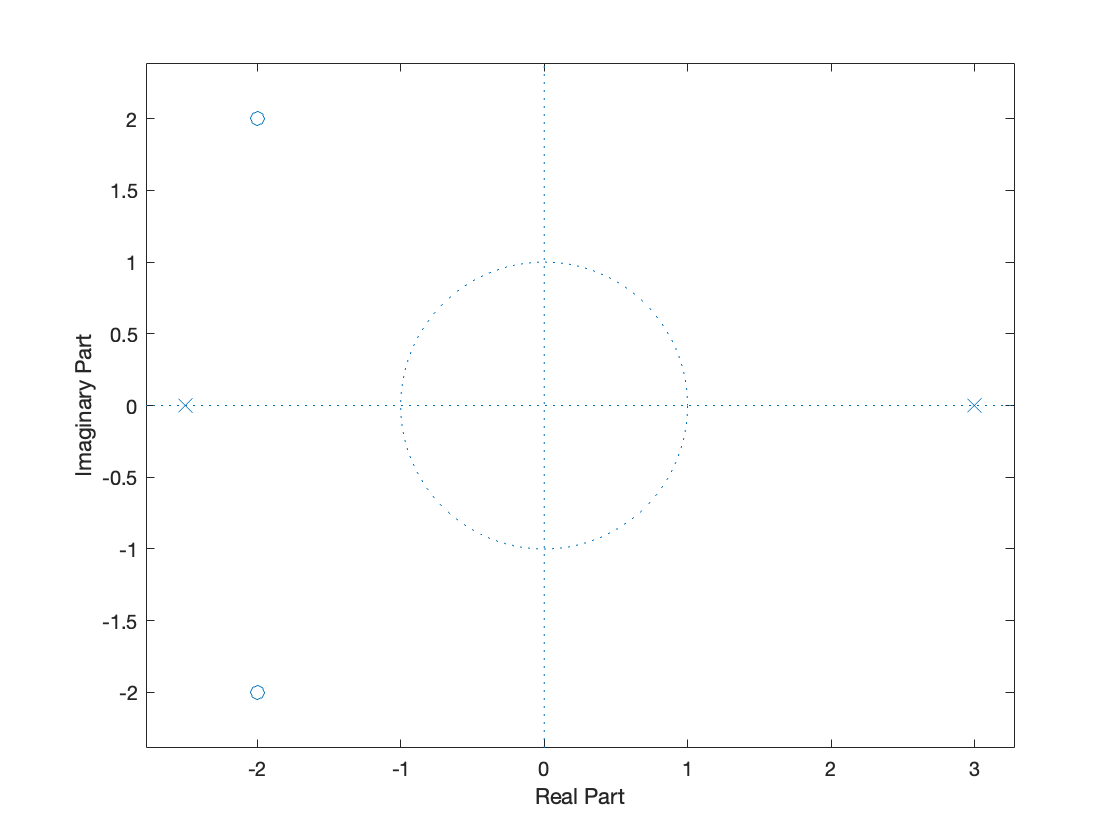

% zplane(n,d)
% hold on
% plot(p,'^r')
% hold off

%iztrans((z.^2+4*z+8)/( z.^2 - 0.5*z - 7.5),z)

Check for incorrect argument data type or missing argument in call to function 'iztrans'.

## Problem 3

## Problem 4

clc; clear all; 
syms z
a = ((z-.1)*(z-.2)*(z-.3)*(z+.8))

$$a = \left(z-\frac{1}{5}\right)\,\left(z+\frac{4}{5}\right)\,\left(z-\frac{1}{10}\right)\,\left(z-\frac{3}{10}\right)$$

b = ((z-.1)*(z-.2)*(z-.3)*(z-.4))

$$b = \left(z-\frac{1}{5}\right)\,\left(z-\frac{2}{5}\right)\,\left(z-\frac{1}{10}\right)\,\left(z-\frac{3}{10}\right)$$

A = sym2poly(a)

A =                          1                       0.2                     -0.37                     0.082                   -0.0048


B = sym2poly(b)

B =                          1                        -1                      0.35                     -0.05                    0.0024




f = tf(A,B,.001)

f =
 
  z^4 + 0.2 z^3 - 0.37 z^2 + 0.082 z - 0.0048
  -------------------------------------------
    z^4 - z^3 + 0.35 z^2 - 0.05 z + 0.0024
 
Sample time: 0.001 seconds
Discrete-time transfer function.



[z p k] = residuez(A,B)

z =           2.99999999999987
      1.61870516990341e-13
      -2.8421709430406e-14
      8.88178419700119e-16


p =          0.400000000000003
         0.299999999999995
         0.200000000000002
        0.0999999999999999


k =     -2


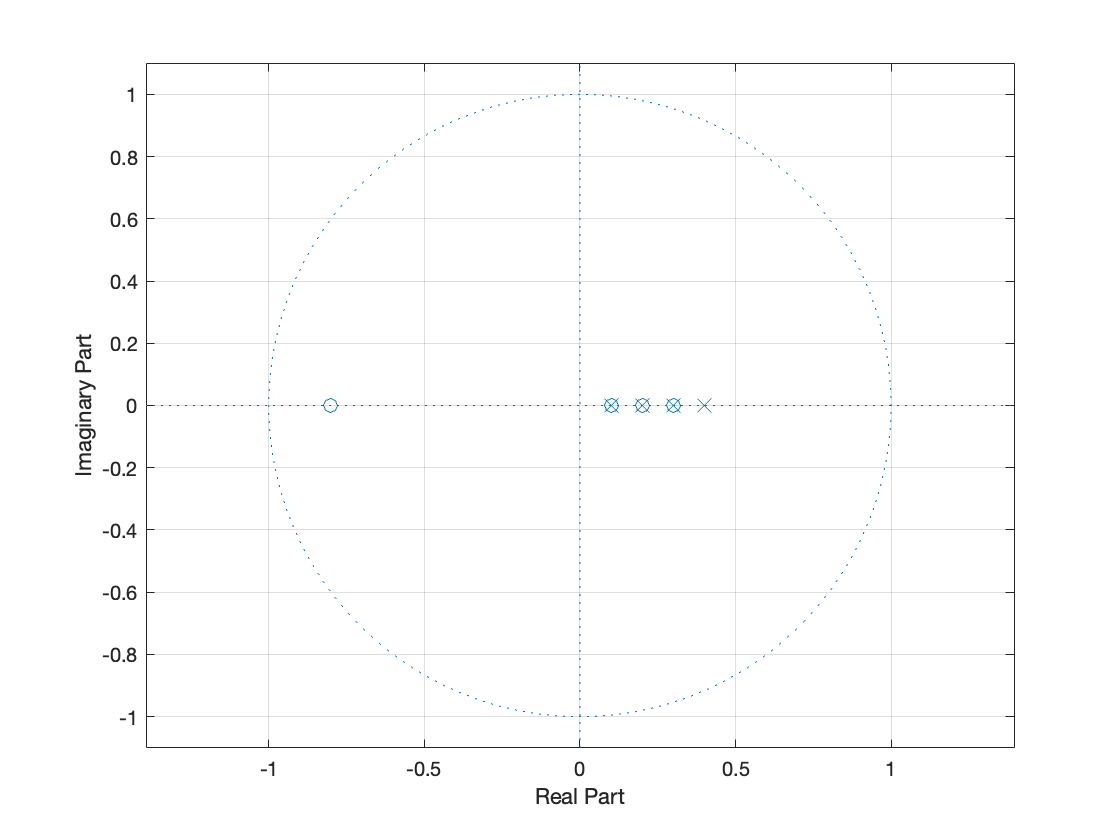

figure()
zplane(A,B)
grid on

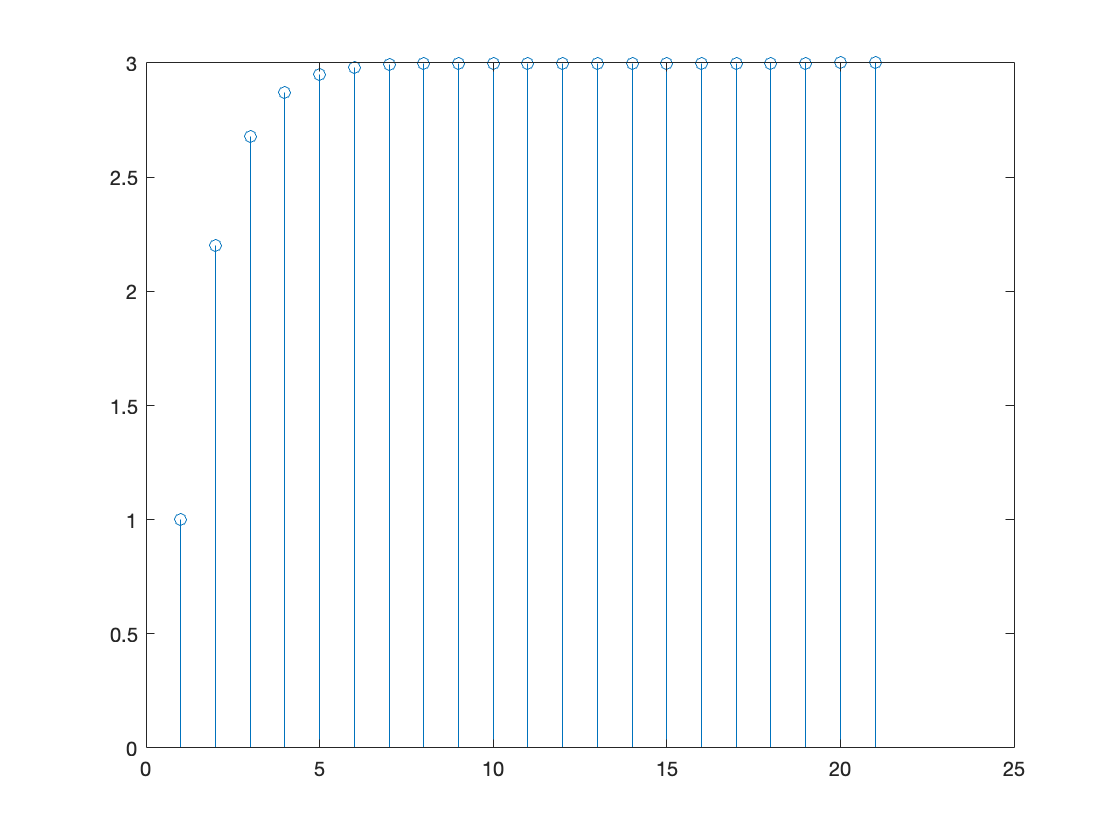

stem(step(f))

## Problem 5

clc; clear all; 
syms t n
x = 4*sin(18*pi*t)+3*cos(10*pi*t)

$$x = 3\,\cos\left(10\,\pi \,t\right)+4\,\sin\left(18\,\pi \,t\right)$$

t = n

$$t = n$$

H = ztrans(x,n)

$$H = \frac{3\,n\,\left(n-1\right)}{n^{2}-2\,n+1}$$


n = sym2poly(3*t*(t-1))

n =      3    -3     0


d = sym2poly(t^2-2*t+1)

d =      1    -2     1


H = tf(n,d)

H =
 
   3 s^2 - 3 s
  -------------
  s^2 - 2 s + 1
 
Continuous-time transfer function.



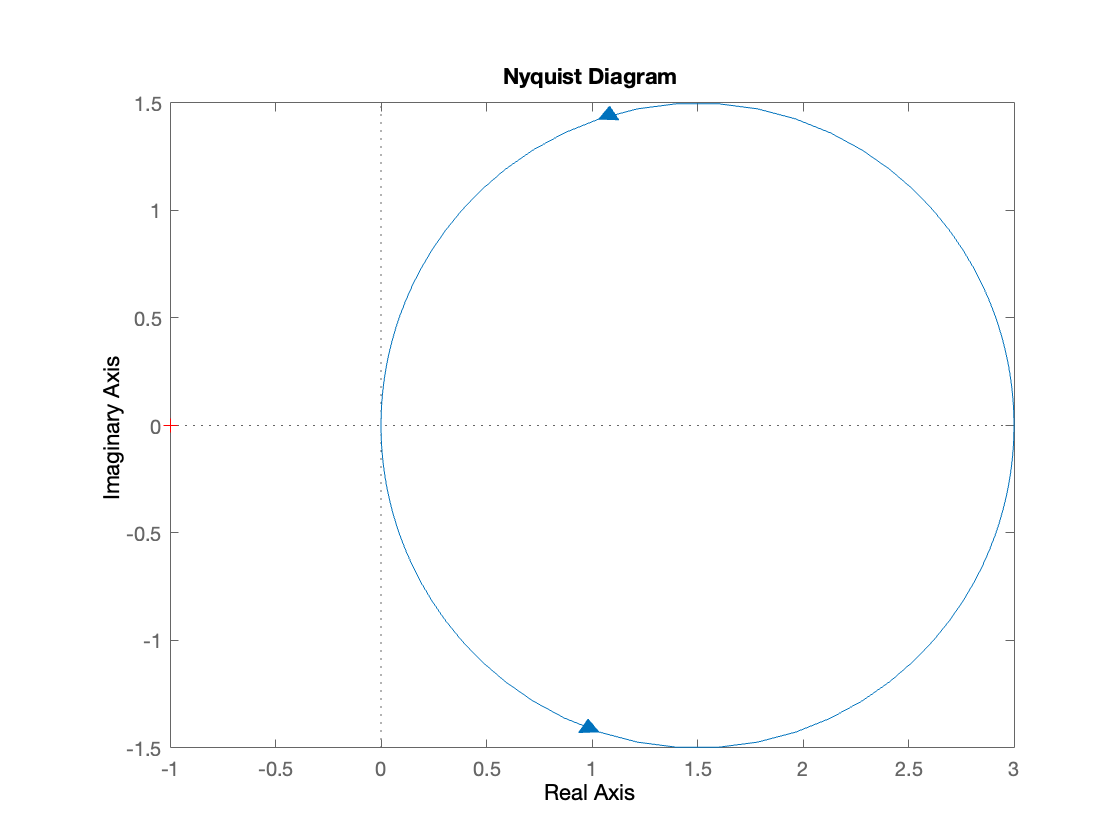

nyquist(H)

nyquistplot(H)

## Problem 6


2*75

## Problem 7

FL = 40

FL = 40

FH = 75

FH = 75

B  = FH-FL

B = 35

k  = FH/B

k = 2.1429

a  = 2*FH/(k)

a = 70

b  = 2*(FH-B)/(k-1)

b = 70